Q1

% ---------------------------------------------
% 1. Define theta (0–180 degrees)
% ---------------------------------------------
theta_deg = linspace(-180,180,2000);
theta = deg2rad(theta_deg);
clf;
% ---------------------------------------------
% 2. Insert your field patterns E(theta) here
% ---------------------------------------------
% Example dummy patterns (DELETE these and use your own)
a=1.25;
lengths = [1/4, 1/2, 1];

E1 = (cos(2*pi*lengths(1)*0.5*cos(theta))-cos(2*pi*lengths(1)*0.5))./sin(theta);
E2 = (cos(2*pi*lengths(2)*0.5*cos(theta))-cos(2*pi*lengths(2)*0.5))./sin(theta);
E3 = (cos(2*pi*lengths(3)*0.5*cos(theta))-cos(2*pi*lengths(3)*0.5))./sin(theta);

E_list = {E1, E2, E3};
labels = {'\lambda/4','\lambda/2','\lambda'};
styles = {'--','-.','-','--','.'};  % matching your textbook

% ---------------------------------------------
% 3. Create polar plot
% ---------------------------------------------
eps = 10^-12;
polarplot(theta,trunc(20*log10(eps+normalise(E1))),'--')

hold on
polarplot(theta,trunc(20*log10(eps+normalise(E2))),'-.')

polarplot(theta,trunc(20*log10(eps+normalise(E3))),'-')

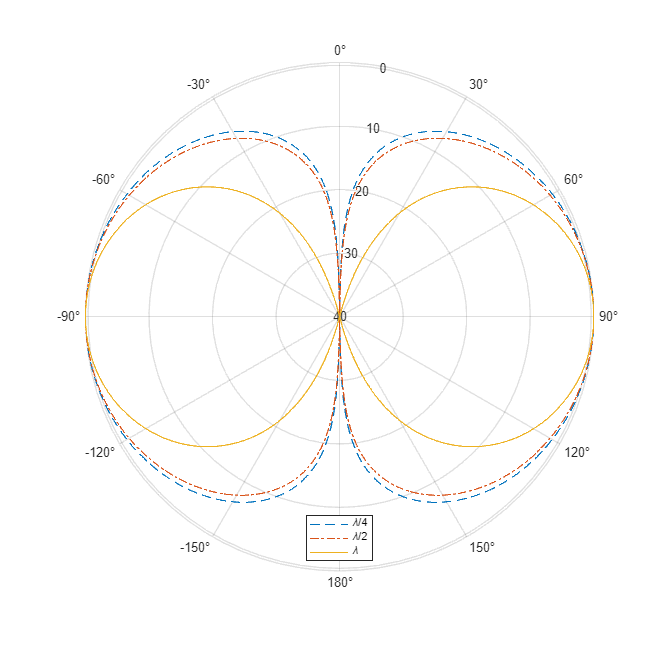

legend(labels,'Location','south')
thetalim([-180 180]);               % only 0–180°
rlim([0 1])
rticks([0 0.25 0.5 0.75 0.99])
rticklabels([40 30 20 10 0]);         % dB rings

thetaticks(-180:30:180);     
ax = gca;
ax.ThetaZeroLocation = 'top';    % 0° at the top
ax.ThetaDir = 'clockwise';       % match antenna books
set(gcf,'position',[1 , 1 , 700 , 700])
hold off

Q2

E4 = (cos(2*pi*1.25*0.5*cos(theta))-cos(2*pi*1.25*0.5))./sin(theta);
polarplot(theta,trunc(20*log10(eps+normalise(E4))),'-')

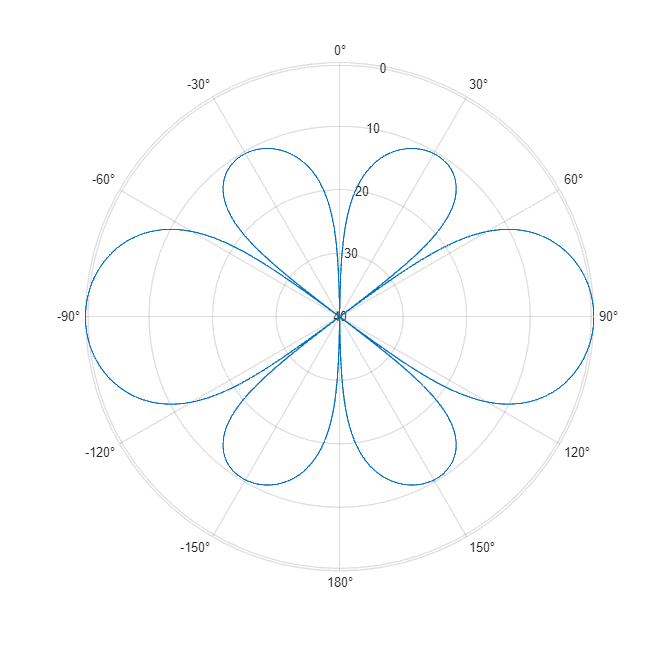

thetalim([-180 180]);               % only 0–180°
rlim([0 1])
rticks([0 0.25 0.5 0.75 0.99])
rticklabels([40 30 20 10 0]);         % dB rings

thetaticks(-180:30:180);     
ax = gca;
ax.ThetaZeroLocation = 'top';    % 0° at the top
ax.ThetaDir = 'clockwise';       % match antenna books
set(gcf,'position',[1 , 1 , 700 , 700])
hold off

Q3

h = [0.25 0.5 1]

h =     0.2500    0.5000    1.0000


theta_deg = linspace(-90,90,1000);
theta = deg2rad(theta_deg);
E1 = sin(theta).*cos(2*pi*h(1)*cos(theta));
E2 = sin(theta).*cos(2*pi*h(2)*cos(theta));
E3 = sin(theta).*cos(2*pi*h(3)*cos(theta));

eps = 10^-12;
polarplot(theta,trunc(20*log10(eps+normalise(E1))),'--')

hold on
polarplot(theta,trunc(20*log10(eps+normalise(E2))),'-.')

polarplot(theta,trunc(20*log10(eps+normalise(E3))),'-')

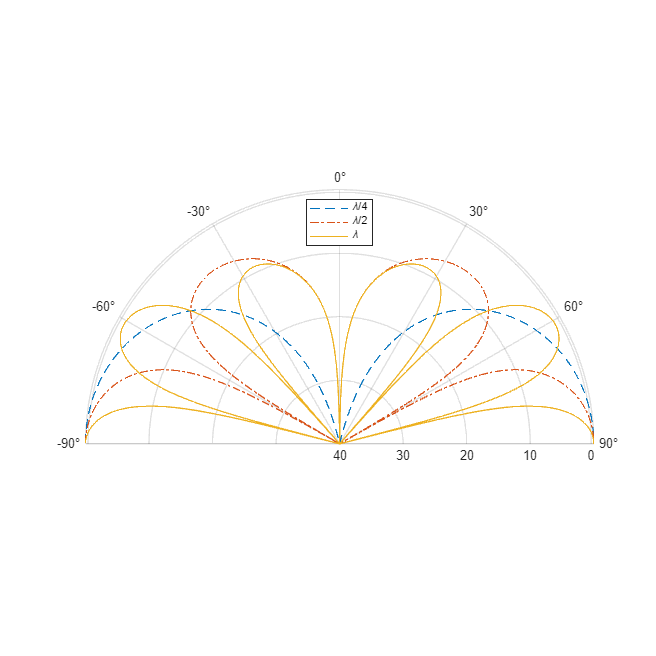

legend(labels,'Location','north')
thetalim([-90 90]);               % only 0–180°
rlim([0 1])
rticks([0 0.25 0.5 0.75 0.99])
rticklabels([40 30 20 10 0]);         % dB rings

thetaticks(-180:30:180);     
ax = gca;
ax.ThetaZeroLocation = 'top';    % 0° at the top
ax.ThetaDir = 'clockwise';       % match antenna books
set(gcf,'position',[1 , 1 , 700 , 700])
hold off

Q4

E4 = sin(theta).*cos(2*pi*5*cos(theta));
polarplot(theta,trunc(20*log10(eps+normalise(E4))))

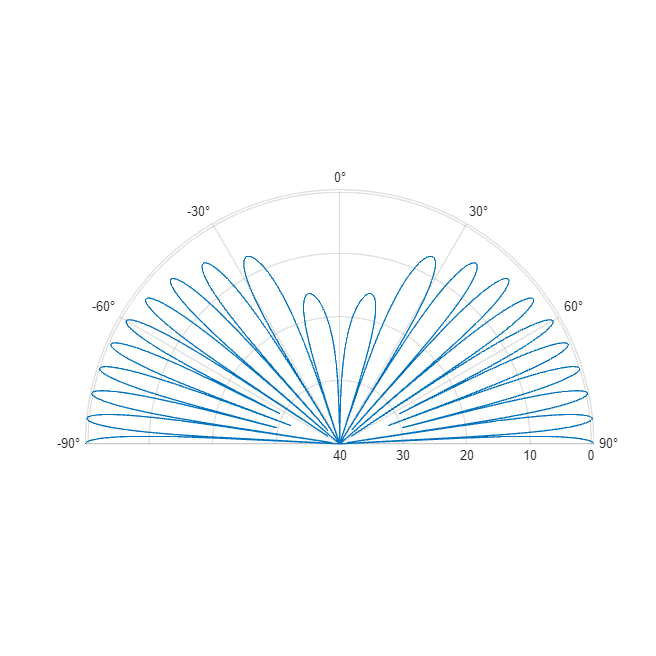


thetalim([-90 90]);               % only 0–180°
rlim([0 1])
rticks([0 0.25 0.5 0.75 0.99])
rticklabels([40 30 20 10 0]);         % dB rings

thetaticks(-180:30:180);     
ax = gca;
ax.ThetaZeroLocation = 'top';    % 0° at the top
ax.ThetaDir = 'clockwise';       % match antenna books
set(gcf,'position',[1 , 1 , 700 , 700])
hold off

Q5

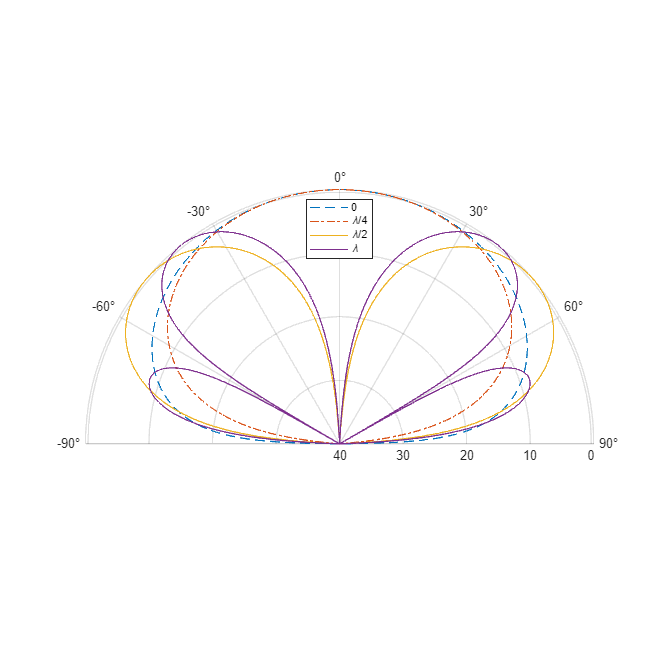

h = [0 0.25 0.5 1];
theta_deg = linspace(-90,90,1000);
theta = deg2rad(theta_deg);
% E1 = cos(theta).*sin(2*pi*0*cos(theta));
E1 = cos(theta);
E2 = cos(theta).*sin(2*pi*h(2)*cos(theta));
E3 = cos(theta).*sin(2*pi*h(3)*cos(theta));
E4 = cos(theta).*sin(2*pi*h(4)*cos(theta));
 

eps = 10^-12;
polarplot(theta,trunc(20*log10(eps+normalise(abs(E1)))),'--')
hold on
polarplot(theta,trunc(20*log10(eps+normalise(abs(E2)))),'-.')
polarplot(theta,trunc(20*log10(eps+normalise(abs(E3)))),'-')
polarplot(theta,trunc(20*log10(eps+normalise(abs(E4)))),'-')
labels = {'0', '\lambda/4', '\lambda/2', '\lambda'};
legend(labels,'Location','north')
thetalim([-90 90]);               % only 0–180°
rlim([0 1])
rticks([0 0.25 0.5 0.75 0.99])
rticklabels([40 30 20 10 0]);         % dB rings

thetaticks(-180:30:180);     
ax = gca;
ax.ThetaZeroLocation = 'top';    % 0° at the top
ax.ThetaDir = 'clockwise';       % match antenna books
set(gcf,'position',[1 , 1 , 700 , 700])
hold off

Q6

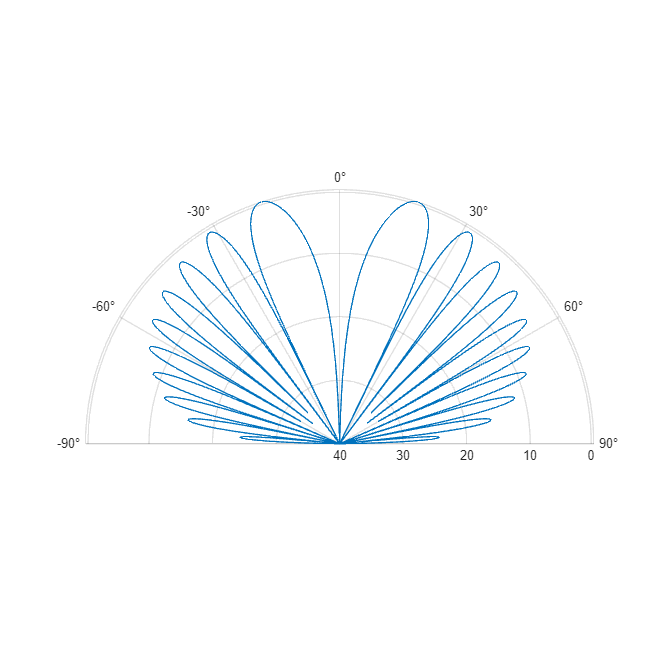

E5 = cos(theta).*sin(2*pi*5*cos(theta));

polarplot(theta,trunc(20*log10(eps+normalise(abs(E5)))),'-')
thetalim([-90 90]);               % only 0–180°
rlim([0 1])
rticks([0 0.25 0.5 0.75 0.99])
rticklabels([40 30 20 10 0]);         % dB rings

thetaticks(-180:30:180);     
ax = gca;
ax.ThetaZeroLocation = 'top';    % 0° at the top
ax.ThetaDir = 'clockwise';       % match antenna books
set(gcf,'position',[1 , 1 , 700 , 700])
hold off

Q7

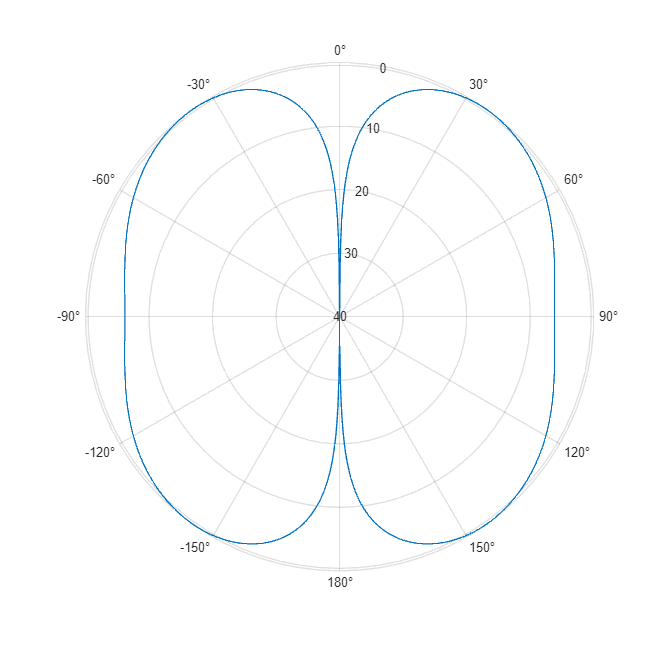

theta_deg = linspace(-180,180,1000);
theta = deg2rad(theta_deg);
E1 = besselj(1,2*pi*0.5*sin(theta));
polarplot(theta,trunc(20*log10(eps+normalise(abs(E1)))),'-')
thetalim([-180 180]);               % only 0–180°
rlim([0 1])
rticks([0 0.25 0.5 0.75 0.99])
rticklabels([40 30 20 10 0]);         % dB rings

thetaticks(-180:30:180);     
ax = gca;
ax.ThetaZeroLocation = 'top';    % 0° at the top
ax.ThetaDir = 'clockwise';       % match antenna books
set(gcf,'position',[1 , 1 , 700 , 700])
hold off

Function to truncate everything below -40dB to -40dB so nulls dont mess up scales.

function y = trunc(x)
    y = ((x+40).*(x+40>0)./40);
end